# Marginal cost data cleaning and regression

## Load marginal cost data

% You have to run this under model_code directory
MCFileDir = "../model_output/";
MCFileName = "MC_*.csv";
MCDataStore = fileDatastore(MCFileDir + MCFileName, "ReadFcn", @importMarginalCost, "UniformRead", true);
MCAll = readall(MCDataStore);
clear MCDataStore;

### Split the data into four seasons

MCAll.Month = month(MCAll.Date);
isSpring = ismember(MCAll.Month, [3,4,5]); 
isSummer = ismember(MCAll.Month, [6,7,8]);
isAutumn = ismember(MCAll.Month, [9,10,11]); 
isWinter = ismember(MCAll.Month, [12,1,2]);
MCSpring = MCAll(isSpring, :);
MCSummer = MCAll(isSummer, :);
MCAutumn = MCAll(isAutumn, :);
MCWinter = MCAll(isWinter, :);

## Select top market participants for study

### Show marginal cost distribution of top 20 market participants

% Create quantity vs marginal cost table of top 20 market participants
numTopParts = 20;
rankedParts = sortrows(groupsummary(MCAll, "PartID"), "GroupCount", "descend");
topPartIDs = rankedParts.PartID(1:numTopParts);
topPartQMCTables = cell(size(topPartIDs));
for n = 1:size(topPartIDs, 1)
    topPartQMCTables{n} = MCAll(MCAll.PartID == topPartIDs(n), :);
end

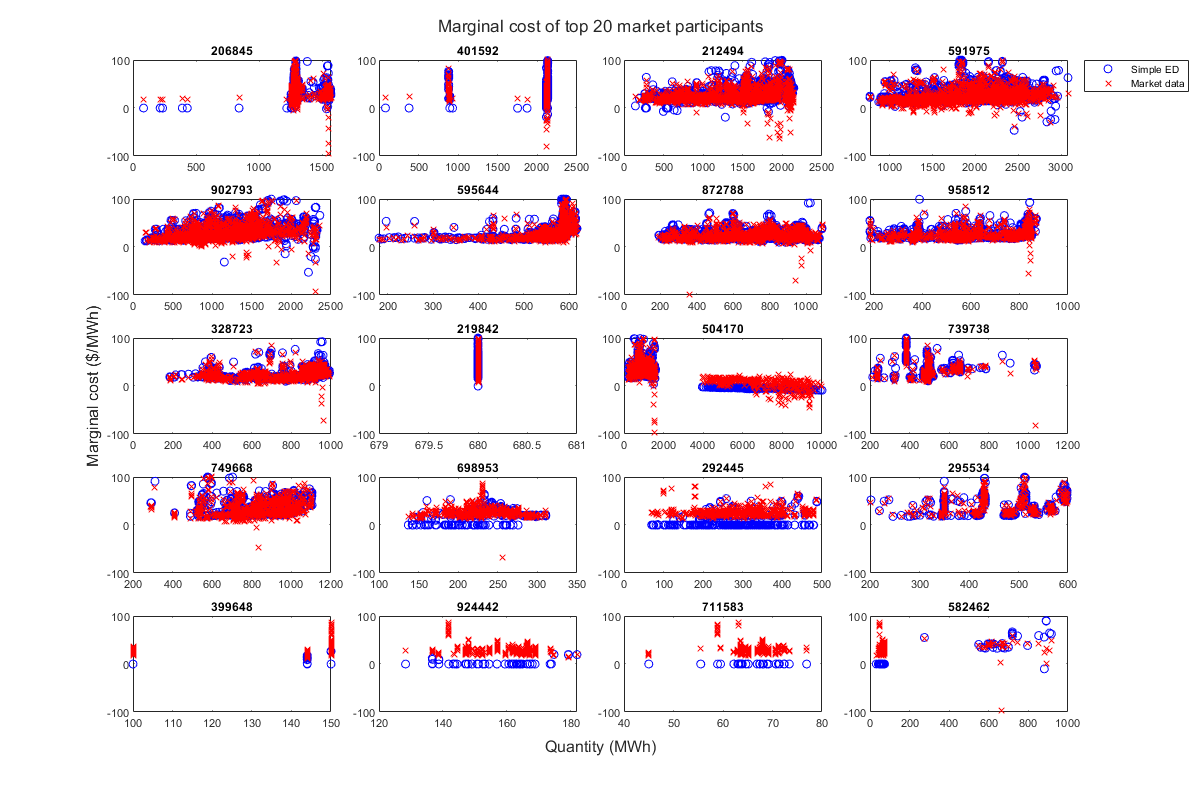

% Plot quantity vs marginal cost of top 20 market participants
plotColumn = 4;
t = tiledlayout(numTopParts/plotColumn, plotColumn, "TileSpacing","compact");
for n = 1:numTopParts
    nexttile;
    partQMCTable = topPartQMCTables{n};
    partID = topPartIDs(n);
    % Marginal cost calculated using price from simple economic dispatch
    scatter(partQMCTable.Awarded, partQMCTable.MCSimpleED, 'bo');
    hold on;
    % Marginal cost calculated using price from ISONE historical data
    scatter(partQMCTable.Awarded, partQMCTable.MCMarket, 'rx');
    hold off; box on;
    title(partID);
    ylim([-100, 100]);
    if n==plotColumn
        legend(["Simple ED", "Market data"], "Location","bestoutside");
    end
end
xlabel(t, "Quantity (MWh)");
ylabel(t, "Marginal cost ($/MWh)");
title(t, "Marginal cost of top 20 market participants");
set(gcf, "Position", [50, 50, 1200, 800]);

### Select top market participants based on their marginal cost distribution

%                      1  2  3  4  5  6  7  8  9 10 11 12 13 14 15 16 17 18 
selPartMask = logical([0; 0; 1; 1; 1; 1; 1; 1; 1; 0; 0; 0; 1; 0; 0; 0; 0; 0; 0; 0]);
selPartIDs = topPartIDs(selPartMask);
selPartQMCTables = topPartQMCTables(selPartMask);
numSelParts = size(selPartIDs, 1);
% selPartIDs = [212494; 591975; 902793; 595644; 872788; 958512; 328723; 739]

### Plot marginal cost distribution of selected market participants

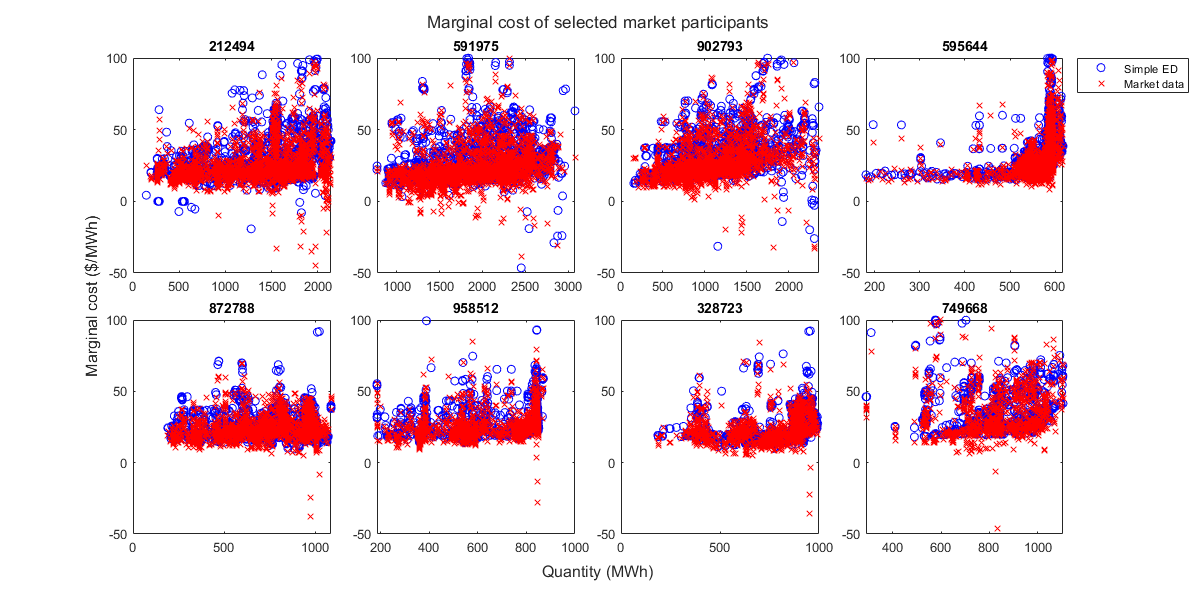

% Plot quantity vs marginal cost of selected market participants
plotColumn = 4;
t = tiledlayout(numSelParts/plotColumn, plotColumn, "TileSpacing","compact");
for n = 1:numSelParts
    nexttile;
    partQMCTable = selPartQMCTables{n};
    partID = selPartIDs(n);
    % Marginal cost calculated using price from simple economic dispatch
    scatter(partQMCTable.Awarded, partQMCTable.MCSimpleED, 'bo');
    hold on;
    % Marginal cost calculated using price from ISONE historical data
    scatter(partQMCTable.Awarded, partQMCTable.MCMarket, 'rx');
    hold off; box on;
    title(partID);
    ylim([-50, 100]);
    if n==plotColumn
        legend(["Simple ED", "Market data"], "Location","bestoutside");
    end
end
xlabel(t, "Quantity (MWh)");
ylabel(t, "Marginal cost ($/MWh)");
title(t, "Marginal cost of selected market participants");
set(gcf, "Position", [50, 50, 1200, 600]);

## Marginal cost data cleaning

### Remove outliers using moving median technique

selCleanedPartQMCTables = cell(numSelParts, 1);
for n=1:numSelParts
    partQMCTable = selPartQMCTables{n};
    partID = selPartIDs(n);
    % Calculate the median marginal cost at each quantity
    MCStats = groupsummary(partQMCTable, "Awarded", "median", "MCMarket");
    [cleanedMedian,outlierIndices,thresholdLow,thresholdHigh] = filloutliers(MCStats.median_MCMarket, ...
        'linear','movmedian',300,'SamplePoints',MCStats.Awarded);
    MCStats.cleanedMedian_MCMarket = cleanedMedian;
    QMCTable = innerjoin(MCStats, partQMCTable,"Keys", "Awarded", "LeftVariables", ...
        ["Awarded", "median_MCMarket", "cleanedMedian_MCMarket"], "RightVariables", ["MCMarket", "Date", "Hour"]);
    % Remove marginal cost data with high deviation from the median
    MCDeviation = QMCTable.MCMarket - QMCTable.cleanedMedian_MCMarket;    
    lowPercent = 20;
    highPercent = 80;
    [hOut,hLow,hHigh,~] = isoutlier(MCDeviation,"percentiles", [lowPercent, highPercent]); 
    cleanedQMCTable = QMCTable(~hOut, :);
    selCleanedPartQMCTables{n} = cleanedQMCTable;
end


### Plot cleaned marginal cost data of selected market participants

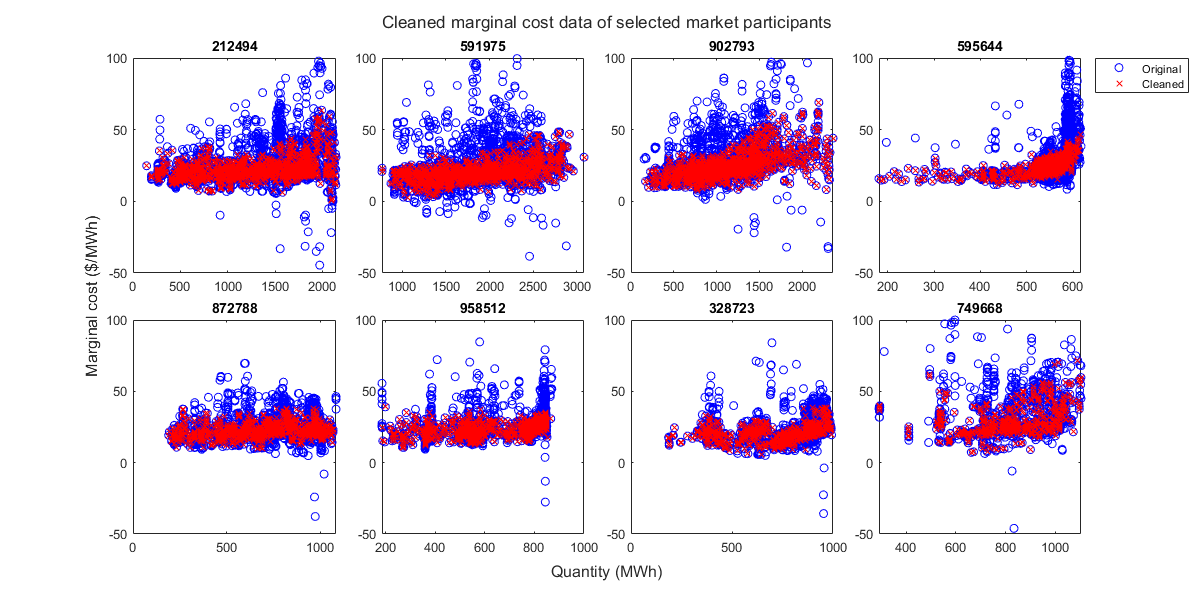

% Plot quantity vs marginal cost of selected market participants
plotColumn = 4;
t = tiledlayout(numSelParts/plotColumn, plotColumn, "TileSpacing","compact");
for n = 1:numSelParts
    nexttile;
    partQMCTable = selPartQMCTables{n};
    partCleanedQMCTable = selCleanedPartQMCTables{n};
    partID = selPartIDs(n);
    % Original marginal cost data
    scatter(partQMCTable.Awarded, partQMCTable.MCMarket, 'bo');
    hold on;
    % Cleaned marginal cost data
    scatter(partCleanedQMCTable.Awarded, partCleanedQMCTable.MCMarket, 'rx');
    hold off; box on;
    title(partID);
    ylim([-50, 100]);
    if n==plotColumn
        legend(["Original", "Cleaned"], "Location","bestoutside");
    end
end
xlabel(t, "Quantity (MWh)");
ylabel(t, "Marginal cost ($/MWh)");
title(t, "Cleaned marginal cost data of selected market participants");

set(gcf, "Position", [50, 50, 1200, 600]);

## Write cleaned maginal cost data to file

for n = 1:numSelParts
    selCleanedPartQMCTables{n} = removevars(selCleanedPartQMCTables{n}, ["median_MCMarket", "cleanedMedian_MCMarket"]);
end
% You have to run this under model_code directory
save("cleanedQMCTables.mat", "selCleanedPartQMCTables", "numSelParts", "selPartIDs", "-mat")